dist_plots("DistancevsOutputFigures",DISTas,DISTveml);


t = 3

DIST_AS = 1.0e+04 *

    0.0011    0.0181    0.0173    0.0203    0.0041    0.0091    0.0229    0.0021    0.0545    0.0018    2.2395    2.2395    2.2395    2.2395    0.0160
    0.0016    0.0260    0.0244    0.0289    0.0055    0.0129    0.0305    0.0030    0.0768    0.0027    2.2395    2.2395    2.2395    2.2395    0.0160
    0.0025    0.0402    0.0384    0.0442    0.0085    0.0197    0.0497    0.0045    0.1182    0.0042    2.2395    2.2395    2.2395    2.2395    0.0160
    0.0043    0.0707    0.0719    0.0769    0.0146    0.0348    0.0982    0.0077    0.2079    0.0074    2.2395    2.2395    2.2395    2.2395    0.0160
    0.0100    0.1651    0.1629    0.1793    0.0336    0.0806    0.2213    0.0178    0.4791    0.0171    2.2395    2.2395    2.2395    2.2395    0.0160
    0.0427    0.7089    0.6631    0.7790    0.1399    0.3453    0.8559    0.0766    2.0438    0.0729    2.2395    2.2395    2.2395    2.2395    0.0160


DIST_AS_CLEAR = 1.0e+04 *

    0.0545
    0.0768
    0.1182
    0.2079
    0.4791
    2.0438


DIST_AS_Normalised_CLEAR =     0.0267
    0.0376
    0.0578
    0.1017
    0.2344
    1.0000


DIST_VEML_Normalised =     0.0315    0.0313    0.0315    0.0322
    0.0446    0.0451    0.0451    0.0457
    0.0660    0.0664    0.0673    0.0677
    0.1095    0.1100    0.1135    0.1126
    0.2254    0.2212    0.2340    0.2325
    1.0000    1.0000    1.0000    1.0000


ans = 1.5515

ans = 1.5395

VEML_model = 1×5 string array
    "RED"    "GREEN"    "BLUE"    "CLEAR"    "MODEL"


VEML_model = 1×5 string array
    "RED"    "GREEN"    "BLUE"    "CLEAR"    "MODEL"


VEML_model = 1×5 string array
    "RED"    "GREEN"    "BLUE"    "CLEAR"    "MODEL"


VEML_model = 1×5 string array
    "RED"    "GREEN"    "BLUE"    "CLEAR"    "MODEL"


VEML_model = 1×5 string array
    "RED"    "GREEN"    "BLUE"    "CLEAR"    "MODEL"


VEML_model = 1×5 string array
    "RED"    "GREEN"    "BLUE"    "CLEAR"    "MODEL"


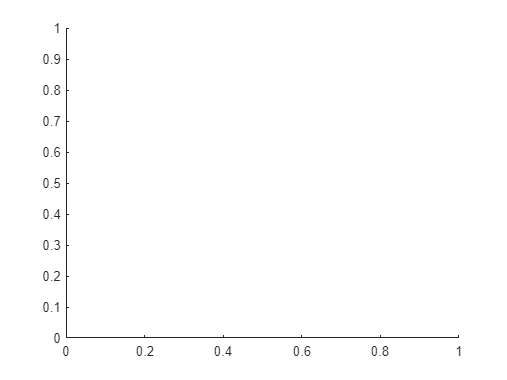

direc = "DistanceModelFigures";
d = 30:-5:5;
t_int = dictionary(1:6,[40, 80, 160, 320, 640, 1280]);
x = 5:0.1:30;
for t = 1:6
    DIST_AS = reshape(cell2mat(DISTas(:,t)),[],15);
    DIST_AS_CLEAR = DIST_AS(:,9);
    DIST_AS_Normalised = DIST_AS(:,1:9)./DIST_AS(6,1:9);
    DIST_AS_Normalised_CLEAR = DIST_AS_Normalised(:,9);

    f_AS = fit(d',DIST_AS_Normalised_CLEAR,'exp2',opts);

    % -----------------------------------------------------
    DIST_VEML = reshape(cell2mat(DISTveml(:,t)),[],15);
    DIST_VEML_Normalised = DIST_VEML(:,11:14)./DIST_VEML(6,11:14);
    DIST_VEML_Normalised_CLEAR = DIST_VEML_Normalised(:,4);
    f_VEML = fit(d',DIST_VEML_Normalised_CLEAR,'exp2');

    % -----------------------------------------------------
    f = figure();
    plot(d,DIST_AS_Normalised(:,1:9), 'LineWidth',1.2);
    hold on
    plot(x,f_AS(x), 'LineWidth', 1.2, 'LineStyle', '--','Color',[0.5 0.5 .5]);
    ax = gca;
    ax.ColorOrder = AS_Colours;

    xlabel("Distance (cm)",'FontSize',14);
    ylabel("Relative Response",'FontSize',14)
    plot_title = sprintf("AS7341 Relative Channel Responses with Distance Model (t_{int} = %d ms)", t_int(t));
    title(plot_title,'FontSize', 18)
    AS_model = [AS_legend,"MODEL"];
    legend(AS_model,'Location','northeast','NumColumns',2);
    set(gcf,'units','normalized','outerposition',[0 0 0.5 0.5]);
    
    filename = sprintf("%s/AS_Normalised_%d_WHITE_distvcounts.jpg",direc,t_int(t));
    saveas(f,filename)
    close(f);
    hold off

    % -----------------------------------------------------
    f = figure();
    plot(d,DIST_VEML_Normalised(:,1:4), 'LineWidth',1.2);
    hold on
    plot(x,f_VEML(x), 'LineWidth', 1.2, 'LineStyle', '--','Color',[0.5 0.5 .5]);
    ax = gca;
    ax.ColorOrder = VEML_Colours;

    xlabel("Distance (cm)",'FontSize',14);
    ylabel("Relative Response",'FontSize',14)
    plot_title = sprintf("VEML6040 Relative Channel Responses with Distance Model (t_{int} = %d ms)", t_int(t));
    title(plot_title,'FontSize', 18)
    VEML_model = [VEML_legend,"MODEL"];
    legend(VEML_model,'Location','northeast','NumColumns',2);
    set(gcf,'units','normalized','outerposition',[0 0 0.5 0.5]);
    
    filename = sprintf("%s/VEML_Normalised_%d_WHITE_distvcounts.jpg",direc,t_int(t));
    saveas(f,filename)
    close(f);
    hold off

    % -----------------------------------------------------

    model_AS_CLEAR = DIST_AS./f_AS(d);
    AS_CLEAR_mean = mean(model_AS_CLEAR);
    AS_CLEAR_dev = std(model_AS_CLEAR);

    f = figure();
    errorbar(1:9,AS_CLEAR_mean(1:9)./AS_CLEAR_mean(9),AS_CLEAR_dev(1:9)./AS_CLEAR_mean(9), 'LineStyle','none','Marker','o','MarkerSize', 3.5,"LineWidth",1.1,'Color',[0.7 0 1])
    grid on
    x_labels = {"CH1","CH2","CH3","CH4","CH5","CH6","CH7","CH8","CLEAR"};
    % xticks(0:10);
    xticklabels(x_labels);
    xlim([0.5,9.5])
    yticks(0:0.1:1);
    ylim([0,1.05]);
    xlabel("Channel",'FontSize',14);
    ylabel("Relative Response",'FontSize',14)
    plot_title = sprintf("AS7341 Relative Channel Responses to White Input (t_{int} = %d ms)", t_int(t));
    title(plot_title,'FontSize',18)
    set(gcf,'units','normalized','outerposition',[0 0 0.5 0.5]);

    filename = sprintf("%s/AS_ALL_Model_Channel_Response_errorbar.jpg",direc);
    saveas(f,filename)
    close(f);

    % -----------------------------------------------------
    f = figure();
    errorbar(1:4,AS_CLEAR_mean([2,4,7,9])./AS_CLEAR_mean(9),AS_CLEAR_dev([2,4,7,9])./AS_CLEAR_mean(9), 'LineStyle','none','Marker','o','MarkerSize', 3.5, "LineWidth",1.1,'Color',[0.7 0 1])
    grid on
    x_labels = {"CH2","CH4","CH7","CLEAR"};
    xticks(1:4);
    xticklabels(x_labels);
    xlim([0.5,4.5])
    yticks(0:0.1:1);
    ylim([0,1.05]);

    xlabel("Channel",'FontSize',14);
    ylabel("Relative Response",'FontSize',14)
    plot_title = sprintf("AS7341 Relative Channel Responses to White Input (t_{int} = %d ms)", t_int(t));
    title(plot_title,'FontSize',18)
    set(gcf,'units','normalized','outerposition',[0 0 0.5 0.5]);

    filename = sprintf("%s/AS_Model_Channel_Response_errorbar.jpg",direc);
    saveas(f,filename)
    close(f);

    % -----------------------------------------------------
    model_VEML_CLEAR = DIST_VEML./f_VEML(d);
    VEML_CLEAR_mean = mean(model_VEML_CLEAR(:,11:14));
    VEML_CLEAR_dev = std(model_VEML_CLEAR(:,11:14));

    f = figure();
    errorbar(1:4,VEML_CLEAR_mean./VEML_CLEAR_mean(4),VEML_CLEAR_dev./VEML_CLEAR_mean(4), 'LineStyle','none','Marker','o','MarkerSize', 3.5,"LineWidth",1.1,'Color',[0.7 0 1])
    grid on
    x_labels = {"RED", "GREEN", "BLUE", "CLEAR"};
    xticks(1:4)
    xticklabels(x_labels);
    xlim([0.5, 4.5])
    yticks(0:0.1:1);
    ylim([0,1.05])

    xlabel("Channel",'FontSize',14);
    ylabel("Relative Response",'FontSize',14)
    plot_title = sprintf("AS7341 Relative Channel Responses to White Input (t_{int} = %d ms)", t_int(t));
    title(plot_title,'FontSize',18)
    set(gcf,'units','normalized','outerposition',[0 0 0.5 0.5]);

    filename = sprintf("%s/VEML_Model_Channel_Response_errorbar.jpg",direc);
    saveas(f,filename)
    close(f);
end

function dist_plots(direc,DISTas,DISTveml)
    AS_legend = ["CH1","CH2","CH3","CH4","CH5","CH6","CH7","CH8","CLEAR"];
    VEML_legend = ["RED", "GREEN", "BLUE", "CLEAR"];
    AS_Colours = [0.7 0 1; 0 0 1; 0 1 1; 0 1 0; 1 1 0; 1 0.6 0; 1 0 0; 0.7 0 0; 0 0 0];
    VEML_Colours = [1 0 0; 0 1 0; 0 0 1; 0 0 0];
    d = 30:-5:5;
    t_int = dictionary(1:6,[40, 80, 160, 320, 640, 1280]);

    for t = 1:6
        DIST_AS = reshape(cell2mat(DISTas(:,t)),[],15);
        DIST_AS_Normalised = DIST_AS(:,1:9)./DIST_AS(6,1:9);
        
        DIST_VEML = reshape(cell2mat(DISTveml(:,t)),[],15);
        DIST_VEML_Normalised = DIST_VEML(:,11:14)./DIST_VEML(6,11:14);
        
        f = figure();
        plot(d,DIST_AS(:,1:9), 'LineWidth',1.2);
        
        ax = gca;
        ax.ColorOrder = AS_Colours;
        
        xlabel("Distance (cm)",'FontSize',14);
        ylabel("Counts",'FontSize',14)
        plot_title = sprintf("AS7341 Channel Responses vs. Distance (t_{int} = %d ms)", t_int(t));
        title(plot_title,'FontSize', 18)
        legend(AS_legend,'Location','northeast','NumColumns',2);
        set(gcf,'units','normalized','outerposition',[0 0 0.5 0.5]);
        
        filename = sprintf("%s/AS_%d_WHITE_distvcounts.jpg",direc,t_int(t));
        saveas(f,filename)
        close(f);
        
        
        f = figure();
        plot(d,DIST_AS_Normalised(:,1:9), 'LineWidth',1.2);
        
        ax = gca;
        ax.ColorOrder = AS_Colours;
        
        xlabel("Distance (cm)",'FontSize',14);
        ylabel("Counts",'FontSize',14)
        plot_title = sprintf("AS7341 Relative Channel Responses vs. Distance (t_{int} = %d ms)", t_int(t));
        title(plot_title,'FontSize', 18)
        legend(AS_legend,'Location','northeast','NumColumns',2);
        set(gcf,'units','normalized','outerposition',[0 0 0.5 0.5]);
        
        filename = sprintf("%s/AS_Normalised_%d_WHITE_distvcounts.jpg",direc,t_int(t));
        saveas(f,filename)
        close(f);

        % -----------------------------------------------------      
        f = figure();
        plot(d,DIST_VEML(:,11:14), 'LineWidth',1.2);
        
        ax = gca;
        ax.ColorOrder = VEML_Colours;
        
        xlabel("Distance (cm)",'FontSize',14);
        ylabel("Counts",'FontSize',14)
        plot_title = sprintf("VEML6040 Channel Responses vs. Distance (t_{int} = %d ms)", t_int(t));
        title(plot_title,'FontSize', 18)
        legend(VEML_legend,'Location','northeast','NumColumns',2);
        set(gcf,'units','normalized','outerposition',[0 0 0.5 0.5]);
        
        filename = sprintf("%s/VEML_%d_WHITE_distvcounts.jpg",direc,t_int(t));
        saveas(f,filename)
        close(f);
        
        % -----------------------------------------------------        
        f = figure();
        plot(d,DIST_VEML_Normalised(:,:), 'LineWidth',1.2);
        
        ax = gca;
        ax.ColorOrder = VEML_Colours;
        
        xlabel("Distance (cm)",'FontSize',14);
        ylabel("Counts",'FontSize',14)
        plot_title = sprintf("VEML6040 Relative Channel Responses vs. Distance (t_{int} = %d ms)", t_int(t));
        title(plot_title,'FontSize', 18)
        legend(VEML_legend,'Location','northeast','NumColumns',2);
        set(gcf,'units','normalized','outerposition',[0 0 0.5 0.5]);
        
        filename = sprintf("%s/VEML_Normalised_%d_WHITE_distvcounts.jpg",direc,t_int(t));
        saveas(f,filename)
        close(f);
    end
end